## Modelling the diurnal cycle with Prochlorococcus

This tutorial shows how to model growth of the marine photoautotrophic bacteria *Prochlorococcus *in an environment with a time-dependent light environment replicating the day - night cycle*.* To do this we use the genome-scale model iSO595.

### Load the genome-scale model

We assume that the COBRA toolbox is installed and initialized. If not, download the toolbox from [https://opencobra.github.io/cobratoolbox/stable/](https://opencobra.github.io/cobratoolbox/stable/) and run *initCobraToolbox*

% Load Prochlorococcus Genome-scale model
model_fn = 'iSO595v6.mat';
model = readCbModel(model_fn);

### Define model light settings

In the following we assume that the light source is monochromatic at 680nm, however it is possible to extend the following calculations to a wave-length dependent light-source.  It is also necessary to calculate a model-specific weight-specific absorption rate, this is achieved by using  the derived pigment absorption spectra provided by Bricaud et al., 2004. The calculations follows the methods in Bricaud et al., 2004, as originally described in Morel and Bricaud, 1981. 

#### Define variables such as pigment concentrations in *Prochlorococcus, *absorption coefficients and refraction index  

At 680nm we can ignore absorption by other pigments than divinyl chlorophyll a and b.

% The ratio of chlorophyll is extracted from the model biomass-function
ci_dvchla = 0.0163 % g / gDW (Partensky 1993 / Casey 2016)

ci_dvchla = 0.0163

ci_dvchlb = 0.0013 % g / gDW (Partensky 1993 / Casey 2016)

ci_dvchlb = 0.0013

absorption_dvchla_680 = 0.0184; % m^2 mg^-1 (Bricaud et al., 2004)
absorption_dvchlb_680 = 0.0018;   % m^2 mg^-1 (Bricaud et al., 2004)
absorption_water_680 = 0.465; % m^-1 (Pope and Fry, 1997)
wavelength = 680;% nm

#### Calculate the packaging effect

This is taking into account that the light-absorbing pigments are not dissolved in the media, but contained with in discrete cells. See Morel and Bricaud, 1981, for a thorough explanation. The packaging effect approaches 0 asymptotically for large cells. Depending on the accuracy needed in the calculation the packaging effect can be assumed ~1 for very small cells, such as *Prochlorococcus. *

diameter = 0.6; % um (Morel et al., 1993)
n_dash = 13.77*1e-3; % imaginary part of refractive index at 675 nm (Stramski et al. 2001)
size_parameter_alpha = diameter*1e3*pi/wavelength; % A variable describing the size ratio between the cell size and wavelength
rho_dash = 4*size_parameter_alpha*n_dash;
Q_a = 1+(2*exp(-rho_dash)/rho_dash)+2*(exp(-rho_dash)-1)/rho_dash^2;
packaging_effect = 1.5*Q_a/rho_dash;

#### Calculate the weight-specific absorption coefficient 

% This coefficient is in units m^2/ g DW biomass
% Multiply by 1e3 to convert from g to mg
absorption_biomass = packaging_effect*(ci_dvchla*1e3*absorption_dvchla_680+ci_dvchlb*1e3*absorption_dvchlb_680);


#### Set the calculated absorption rate as a model parameter for the exchange reaction of light

absorption_matrix = zeros(1,2);
absorption_matrix(1) = absorption_water_680;
absorption_matrix(2) = absorption_biomass;
model  = setLight(model, {'LightEX'}, absorption_matrix);

### Make layout with the COMETS toolbox

layout = CometsLayout();
layout = layout.addModel(model);

### Set initial conditions and parameters

We use a single cell as the model layout

% Set initial amount of cells to 1e-7 g
layout = setInitialPop(layout, '1x1', 1e-7); 

% Set simulation parameters
layout.params.writeMediaLog = true;
layout.params.mediaLogName = [pwd '/mediaLog.m'];
layout.params.writeBiomassLog = true;
layout.params.biomassLogName = [pwd '/biomassLog.m'];

layout.params.maxCycles = 480;
layout.params.timeStep = 0.1;
layout.params.defaultDiffConst = 0;
layout.params.objectiveStyle = 'MAX_OBJECTIVE_MIN_TOTAL';

### Define medium

We here a light-limited medium, i.e. no limitation on the uptake of nitrogen, phosphate, sulfate or other compounds.

layout = layout.setMedia('Ammonia[e]', 1000); 
layout = layout.setMedia('HCO3[e]', 1000);
layout = layout.setMedia('CO2[e]', 1000);
layout = layout.setMedia('H[e]', 1000);
layout = layout.setMedia('Orthophosphate[e]', 1000); 
layout = layout.setMedia('H2O[e]', 1000);

layout = layout.setMedia('Cadmium[e]', 1000);
layout = layout.setMedia('Calcium_cation[e]', 1000);
layout = layout.setMedia('Chloride_ion[e]', 1000);
layout = layout.setMedia('Cobalt_ion[e]', 1000);
layout = layout.setMedia('Copper[e]', 1000);

layout = layout.setMedia('Fe2[e]', 1000);
layout = layout.setMedia('Magnesium_cation[e]', 1000);
layout = layout.setMedia('Molybdenum[e]', 1000);
layout = layout.setMedia('K[e]', 1000);
layout = layout.setMedia('Selenate[e]', 1000);
layout = layout.setMedia('Sodium_cation[e]', 1000);
layout = layout.setMedia('Strontium_cation[e]', 1000);
layout = layout.setMedia('Sulfate[e]', 1000);
layout = layout.setMedia('Zn2[e]', 1000);
layout = layout.setMedia('Hydrogen_sulfide[e]',1000);


### Set light conditions

Light is modelled as individual photons the value is the number of photons (in mmol) absorbed by the organism at each timepoint. While it is treated like any other metabolite, it is more reasonable to consider it light intensity than a *concentration* which the other compounds in the media are. To model natural light conditions we use the periodic function called *half sin* which is basically *max(0, f(t))* with 

*f(t) = A sin(wt+b) + C*

Here *A* is the amplitude, *w* the angular frequency (*w = 2*pi/T*), b the phase and C the offset.  

Other periodic functions are available: step function, sine and cosine. We here define global light conditions. It is also possible to set detailed condtions for each grid cell in the layout by using the function *setDetailedPeriodicMedia*

We here define the period to 24 hours with an amplitude of 0.04 [mmol photons (Q) m^-2 s^-1]

% define parameters
amplitude = 0.04; % mmol Q / m^2 / s
function_name = 'half_sin';
period = 24; % In hours
phase = 0;
offset = 0;
photon_metabolite_id = 'Photon[e]';

% Set globally changing light conditions
layout = layout.setGlobalPeriodicMedia(photon_metabolite_id, function_name, amplitude, period,phase,offset);


### Run comets

If you have set up the environmental variable 'COMETS_HOME' to where comets is installed, you can run comets with the function *runComets. *Not that this wont work if there is any spaces in the 'COMETS_HOME' path (e.g. avoid the *Program Files* folder). 

Otherwise you can launch the GUI COMETS and load in the layout file *comets_layout.txt.*

% Runs comets and produce the output files mediaLog.m and biomassLog.m
runComets(layout)

Log file C:\Users\ilija\Dropbox (BOSTON UNIVERSITY)\Methods Paper Materials\COMETS_Examples\COMETS_example_Diurnal_Cycle\Matlab/mediaLog.m already exists! Deleting it before COMETS execution...
Log file C:\Users\ilija\Dropbox (BOSTON UNIVERSITY)\Methods Paper Materials\COMETS_Examples\COMETS_example_Diurnal_Cycle\Matlab/biomassLog.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\Users\ilija\Dropbox (BOSTON UNIVERSITY)\Methods Paper Materials\COMETS_Examples\COMETS_example_Diurnal_Cycle\Matlab


ans =     '
     C:\Users\ilija\Dropbox (BOSTON UNIVERSITY)\Methods Paper Materials\COMETS_Examples\COMETS_example_Diurnal_Cycle\Matlab>java -classpath "C:\Program Files\comets/lib/colt/lib/colt.jar";"C:\Program Files\comets/lib/colt/lib/concurrent.jar";"C:\Program Files\comets/lib/jdistlib-0.4.5-bin.jar";"C:\Program Files\comets/lib/commons-lang3-3.9/commons-lang3-3.9-sources.jar";"C:\Program Files\comets/lib/commons-lang3-3.9/commons-lang3-3.9.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-simple-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-sampling-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-jmh-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-core-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-client-api-1.0.jar";"C:\Program Files\comets/lib/commons-math3-3.6.1/commons-math3-3.6.1.jar";"C:\Program Files\comets/lib/commons-math3-3.6.1/commons-math3-3.6.1-tools.jar";"C:\Program Files\comets/

### Write layout to file

If you want to run Comets in the stand-alone GUI use this function instead of runComets to export layout and model file.

createCometsFiles(layout,pwd);

### Load results

media = parseMediaLog('mediaLog.m');
biomass = parseBiomassLog('biomassLog.m');

### Plot results

Plot the light intensity and growth

figure('Name', 'Biomass and Light');
mets_to_plot = {'Photon[e]'}

mets_to_plot = 1×1 cell array
    {'Photon[e]'}


p = plotMediaTimecourse(media, mets_to_plot, false);
set(p,'linewidth',2, 'color', 'b');
legend('Location','northeast')
ylabel('Light flux (mmol photons m^{-2} s^{-1})');
ylim([0 0.045]);

yyaxis right
p1 = plot(biomass.biomass, 'DisplayName', 'Biomass')

p1 =   Line (Biomass) with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×481 double]
              YData: [1×481 double]
              ZData: [1×0 double]

  Show all properties


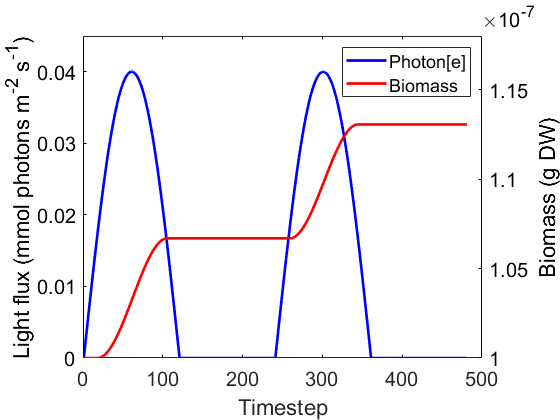

set(p1,'linewidth',2, 'color', 'r');
xlabel('Timestep');
ylabel('Biomass (g DW)');
ax = gca;
ax.YAxis(2).Color = 'k';
ylim([1e-7 1.18e-7]);
set(gca,'FontName','Helvetica');
set(gca,'FontSize',15);

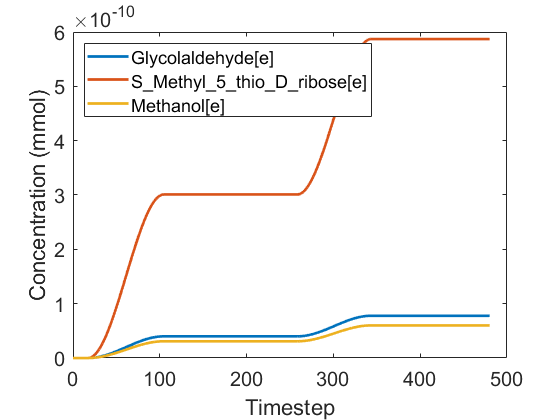

figure('Name', 'Products');
mets_to_plot = {'Glycolaldehyde[e]', 'S_Methyl_5_thio_D_ribose[e]', 'Methanol[e]'};
p3 = plotMediaTimecourse(media, mets_to_plot, false);
set(p3,'linewidth',2);
legend('Location','northwest', 'NumColumns', 1);
set(gca,'FontName','Helvetica');
set(gca,'FontSize',15);

## References

- Bricaud, Annick, et al. "Natural variability of phytoplanktonic  absorption in oceanic waters: Influence of the size structure of algal  populations." *Journal of Geophysical Research: Oceans* 109.C11 (2004).

- Morel, André, and Annick Bricaud. "Theoretical results concerning light  absorption in a discrete medium, and application to specific absorption  of phytoplankton." *Deep Sea Research Part A. Oceanographic Research Papers* 28.11 (1981): 1375-1393.

- Partensky, Frédéric, et al. "Photoacclimation of Prochlorococcus  sp.(Prochlorophyta) strains isolated from the North Atlantic and the  Mediterranean Sea." *Plant Physiology* 101.1 (1993): 285-296.

- Casey, John R., et al. "Adaptive evolution of phosphorus metabolism in Prochlorococcus." *Msystems* 1.6 (2016): e00065-16

- Pope, Robin M., and Edward S. Fry. "Absorption spectrum (380–700 nm) of pure water. II. Integrating cavity measurements." *Applied optics* 36.33 (1997): 8710-8723.

- Stramski, Dariusz, Annick Bricaud, and Andre Morel. "Modeling the  inherent optical properties of the ocean based on the detailed  composition of the planktonic community." *Applied Optics* 40.18 (2001): 2929-2945.